clear, close all, clc;

**Define system parameters**

%Constants
m_p = 0.215;    %(kg)       Pendulum mass
m_c = 1.608;    %(kg)       Cart mass
L   = 0.314;    %(m)        Effective pendulum half-length
I_o = 7.06e-3;  %(kg.m^2)   Pendulum moment of inertia about centre of mass
R   = 0.16;     %(ohm)      Motor terminal resistance
r   = 0.0184;   %(m)        Pinion radius
k_g = 3.71;     %(m/m)      Gearing ratio
k_m = 0.0168;   %(V.s/rad)  Motor back EMF constant
c   = 0;        %(N.s/m)    Damping on cart
g   = 9.81;     %(m/s^2)    Acceleration due to gravity
dx  = 0.1;      %(m)        Step size of cart.

%Matricies
A3_2 = (-m_p^2*L^2*g)/((m_c + m_p)*I_o + m_c*m_p*L^2);
A3_3 = (I_o + m_p*L^2)*(c*R*r^2 + k_m^2*k_g^2)/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r^2);
A4_2 = (m_c + m_p)*m_p*L*g/((m_c + m_p)*I_o + m_c*m_p*L^2);
A4_3 = -m_p*L*(c*R*r^2 + k_m^2*k_g^2)/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r^2);

A = [0,   0,    1,    0;
     0,   0,    0,    1;
     0,   A3_2, A3_3, 0;
     0,   A4_2, A4_3, 0];
 
B3 = -(I_o + m_p*L^2)*k_m*k_g/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r);
B4 = m_p*L*k_m*k_g/(((m_c + m_p)*I_o + m_c*m_p*L^2)*R*r);

B = [0;0;B3;B4];

C = [1 0 0 0]; %eye(4); %make it eye(4) for the real thing, make it [1 0 0 0] so that only x is plotted for easy reading in matlab
D = 0;


**Make state space object**

sys = ss(A, B, C, D);

%check stability
eig(sys);


**Design control gains**

%Place poles method
%poles = [-1+5i, -1-5i, -1, -2];
poles = [-3 -4 -5 -6];
K = place(A, B, poles);
ACL = A - B*K;
sys = ss(ACL, B, C, D);

%tracking gain N
C1 = [1 0 0 0];
N = -inv(C1*inv(ACL)*B); 


**Responses**

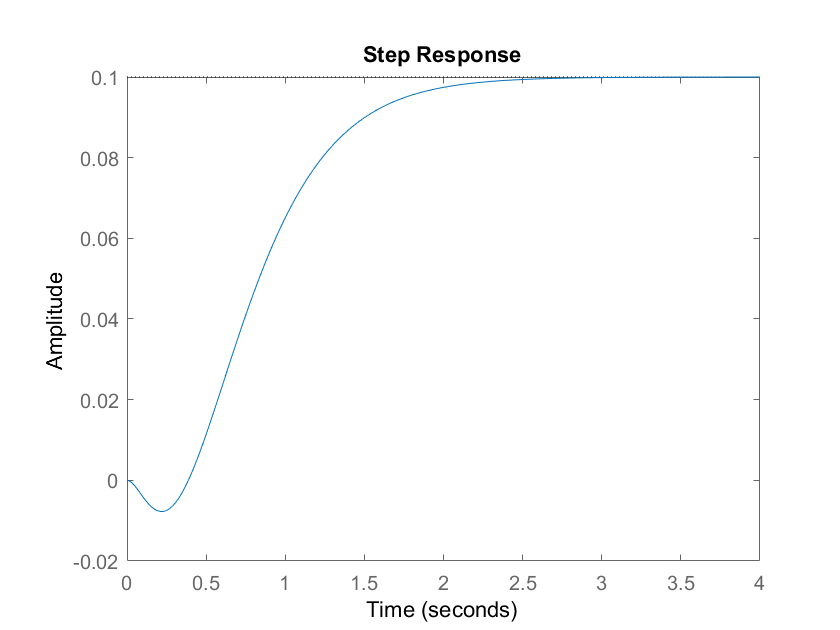


sys.B = dx*N*sys.B; %As it is tracking a dx step input, also include tracking gain N


figure
step(sys);